spectra = importdata('spectra.csv');
lambdaStart = importdata('lambda_start.csv');
lambdaDelta = importdata('lambda_delta.csv');
starNames = importdata('star_names.csv')

starNames = 7×1 cell array
    {'HD30584'  }
    {'HD10032'  }
    {'HD64191'  }
    {'HD5211'   }
    {'HD56030'  }
    {'HD94028'  }
    {'SAO102986'}



lambdaPr = 656.28; %нм
speedOfLight = 299792.458; %км/c

numofstars = size(spectra, 2)

numofstars = 7

nObs = size(spectra, 1)

nObs = 357

lambdaEnd = lambdaStart + (nObs - 1)*lambdaDelta

lambdaEnd = 679.8600

lambda = (lambdaStart : lambdaDelta : lambdaEnd)'

lambda =   630.0200
  630.1600
  630.3000
  630.4400
  630.5800
  630.7200
  630.8600
  631.0000
  631.1400
  631.2800



movaway = []


movaway =

     []



fg1 = figure;
for i = 1:numofstars
    s = spectra(:,i);
    [sHa, idx] = min(s)
    speed(i,:) =  ((lambda(idx) / lambdaPr) - 1) * speedOfLight
    if (((lambda(idx) / lambdaPr) - 1) * speedOfLight) > 0
        movaway = [movaway starNames(i, :)]
        plot(lambda, s, "LineStyle","-", "LineWidth", 3)
        hold on
         
    else
        plot(lambda, s, "LineStyle","--", "LineWidth", 1)
        hold on
    end
end

sHa = 1.6340e-13

idx = 188

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
 -228.4029


sHa = 7.2400e-14

idx = 187

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
 -228.4029


sHa = 3.1440e-14

idx = 188

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
 -228.4029


sHa = 5.3640e-14

idx = 189

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
 -228.4029


movaway = 1×1 cell array
    {'HD5211'}


sHa = 6.8980e-14

idx = 189

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
 -228.4029


movaway = 1×2 cell array
    {'HD5211'}    {'HD56030'}


sHa = 9.8010e-14

idx = 191

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
 -228.4029


movaway = 1×3 cell array
    {'HD5211'}    {'HD56030'}    {'HD94028'}


sHa = 2.2140e-14

idx = 185

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
 -228.4029


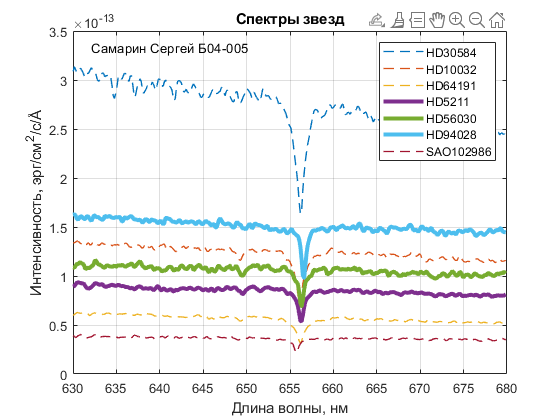



legend(starNames)
title('Спектры звезд')
ylabel(['Интенсивность, эрг/см^2/c/', char(197)])
xlabel('Длина волны, нм')
text(lambdaStart + 2, max(s)*8.3, ['Самарин Сергей Б04-005'])
grid on
set(fg1, 'visible', 'on')
saveas(fg1, 'spectra.png')